## ***Problem Statement******: *****Consider a plane slab of large surface area and thickness 0.2m. Find temperature distribution and Rate of heat transfer at different location for given temperature and convection boundary conditions.**

## ***Assumptions******: *****1D, Steady state, variable thermal conductivity, non zero heat generation.**

## ***Parameters*****: **

- **Temperature at far left surface of slab = 373K**

- **Convection condition at far right of the slab = Air at **$T_{\infty } =373K$** and **$h=45\;\left(\frac{W}{m^2 *K}\right)$

- 
$$k=10+80*x\;\left(\frac{W}{m*K}\right)$$
 

- **L = 0.2m**

- 
$${\mathit{\mathbf{q}}}_{\mathrm{gen}} =30000\;\left(\frac{W}{m^3 }\right)$$


- **No. of nodes = 5, 25, 50, 100, 500, 1000...**

## ***Find*****: **

- **Temperature distribution (done)**

- **Heat transfer flux at different locations (done)**

- **Analytical solution    done **

- **Numerical solution    done **

- **Plot graph comparing analytical and numerical solution   done **

- **determine how much nodes is sufficient for numerical method  **

- **No. of iterations of each selection of nodes  **

- **error graph per iteration **

- **Code time execution for each value of nodes     done**

***1. Setting the parameters of the problem:***

clear
clc

format long  %Large no of float points are used to reduce the trucation error.
N = 20;  % No. of nodes 
L = 0.2;  % Thickness of plane slab
delta_x = L/(N-1);   % Element size
x = 0:delta_x:L;
k_varx = 10 + 80*x;
e = 0.000001;     % error thresold
q_gen = 30000;
h = 45;           % Heat transfer conefficent of air  
T_inf = 303;     % Air temperature

***2. Analytical Solution:***

x_ana = linspace(0,0.2,100);
T_ana = -37.5*x_ana - 14.9357*(log(80*x_ana + 10)) + 407.3871;
Q_flux_ana = 3000*x_ana + 1569.856;

***3. Numerical Solution:***

T_guess = zeros(1,N);  % Initial guess for gauss-seidel iteration 
T_guess(1) = 373;

T_current = T_guess;

% First iteration
tic;
i = 0;
Max_Error = 0;
[T_new, AbsoluteError, Max_Error, i] = NumericalMethod(T_current, N,x, delta_x, h, q_gen, T_inf, i, Max_Error); 

% iterating until the solution converges (error goes below the thresold value)
while max(AbsoluteError) > e
    [T_new, AbsoluteError, Max_Error, i] = NumericalMethod(T_new,N,x, delta_x,h, q_gen,T_inf,i,Max_Error);
end
TimeElapsed_Nodes = toc

TimeElapsed_Nodes =    0.499969400000000


Iterations_Nodes = i

Iterations_Nodes =         2250


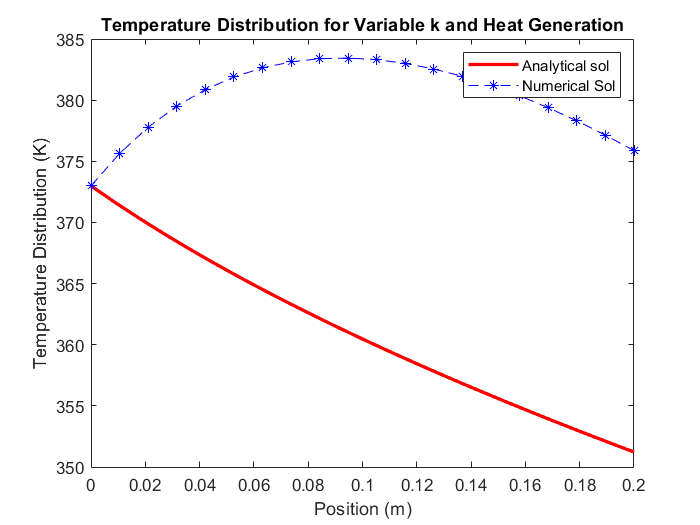


% Heat flux by numerical method
%for n=1:N
    %if n==1
        %Q_flux_numerical(n)= -k_0*(1+beta*T_new(n))*((T_new(n+1)-T_new(n))/delta_x) + q_gen*delta_x/2;
   % elseif n>=2 && n<= N-1
        %Q_flux_numerical(n)= -k_0*(1+beta*T_new(n))*((T_new(n+1)-T_new(n-1))/(2*delta_x)) + q_gen*delta_x;
   % else 
        %Q_flux_numerical(n)= -k_0*(1+beta*T_new(n))*((T_new(n)-T_new(n-1))/delta_x) + q_gen*delta_x/2;
    %end
%end

plot(x_ana, T_ana, "r", "LineWidth", 2)
hold on 
plot(x, T_new, "b--*")
xlabel("Position (m)")
ylabel("Temperature Distribution (K)")
legend("Analytical sol","Numerical Sol")
title("Temperature Distribution for Variable k and Heat Generation")
hold off

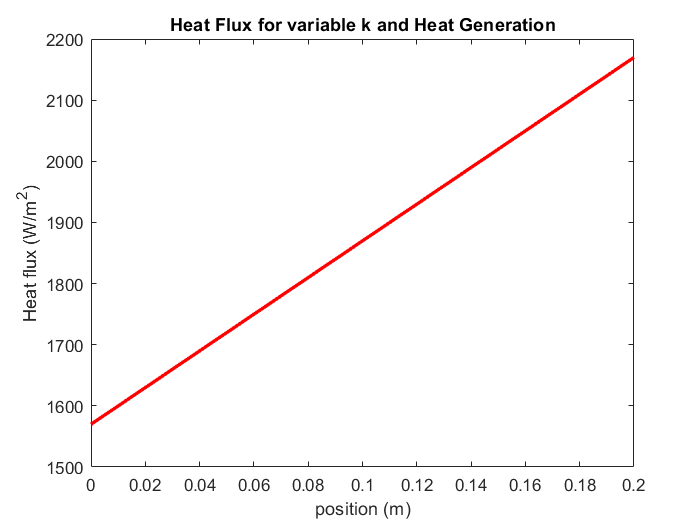


plot(x_ana, Q_flux_ana, "r", "LineWidth", 2)
hold on 
%plot(x_110Nodes, Q_flux_numerical, "b--*")
xlabel("position (m)")
ylabel("Heat flux (W/m^2)")
title("Heat Flux for variable k and Heat Generation")
hold off

format short


***4. Numerical Iterator based on Gauss-Siedel method:***

function [T_new, AbsoluteError, Max_Error, i] = NumericalMethod(T_current, N,x, delta_x, h, q_gen,T_inf, i, Max_Error)
    T_new(1) = 373; % far left node is at constant temperature 
    for n = 2:N
        if n < N % For inner nodes 
            % use of latest value for the calculation of next temperature at different position 
            T_new(n) =  (T_current(n+1)*(40*(x(n)+x(n+1))+10)+T_new(n-1)*(40*(x(n)+x(n-1))+10)+q_gen*(delta_x^2))/(20+80*x(n)+40*(x(n+1)+x(n-1)));
            
        elseif n == N  % For Node at the far right surface influenced by convection
            T_new(n) = (T_new(n-1)*(80*x(n)+10) + h*delta_x*T_inf + q_gen*(delta_x^2)/2)/(10+80*x(n) + h*delta_x);
        end
        
    end
    
    i = i +1;
    AbsoluteError = abs(T_new - T_current); % absolute error at each node
    
end